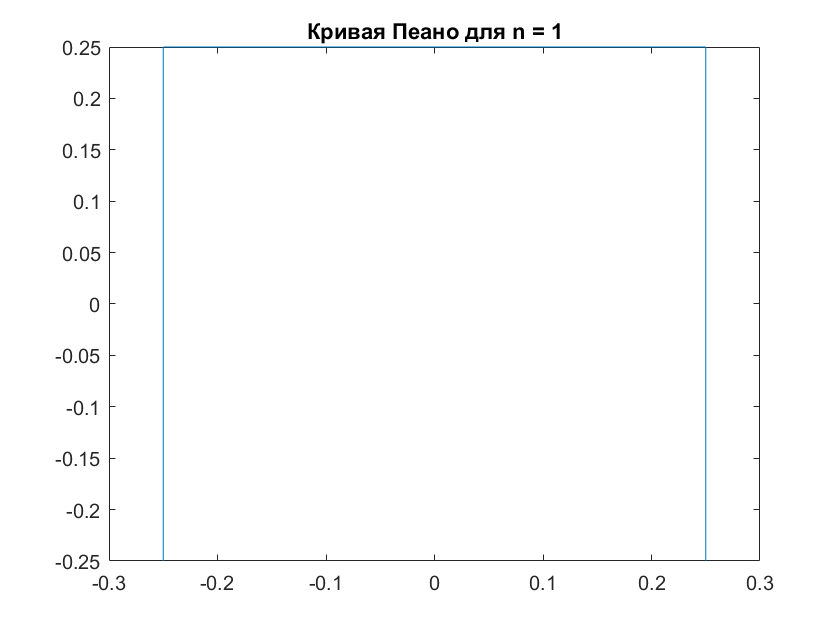

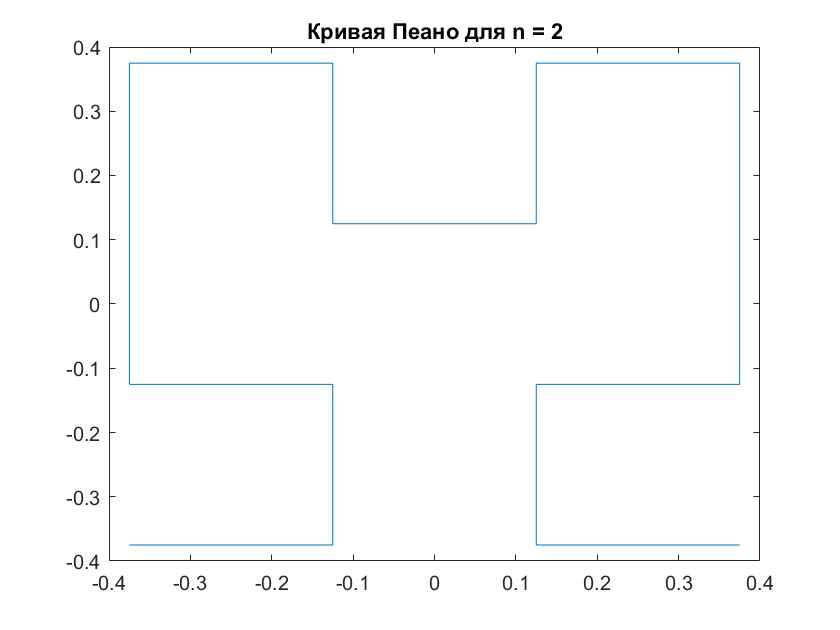

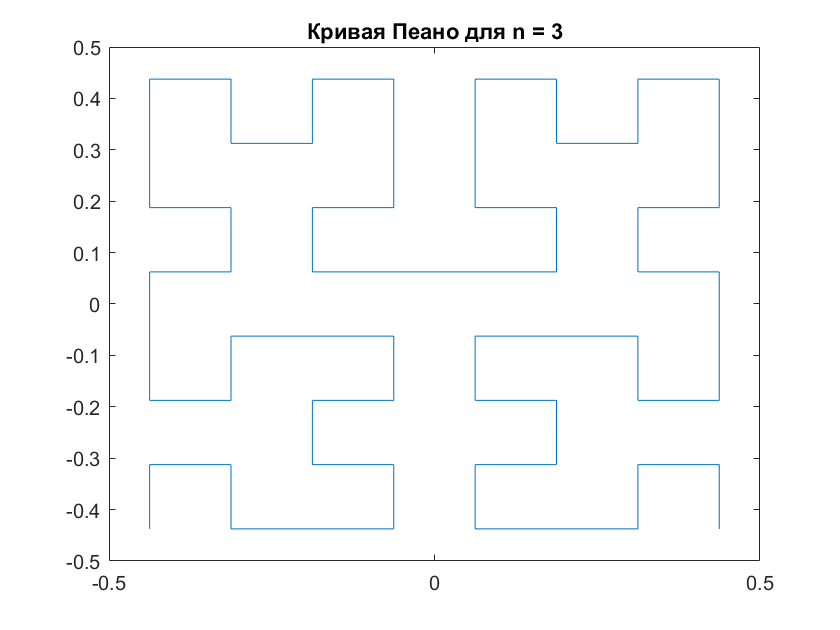

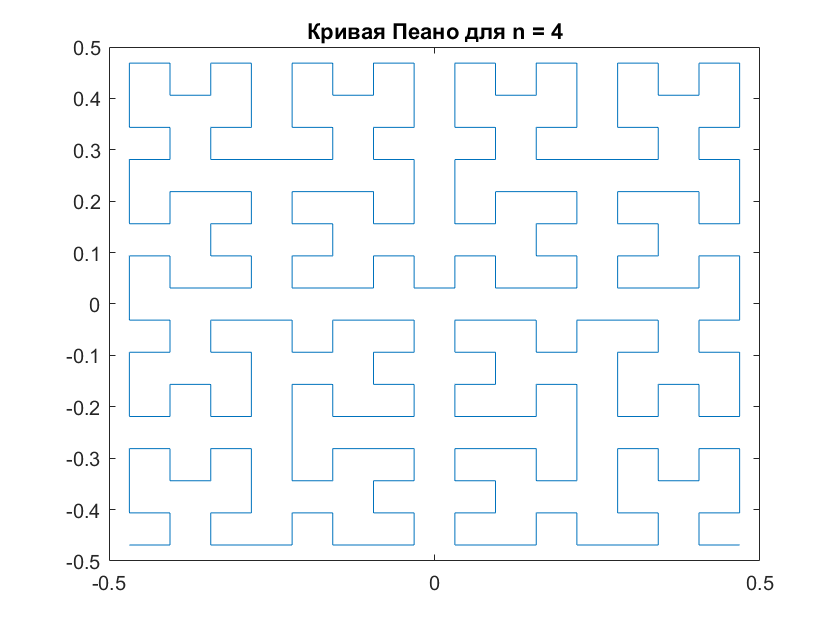

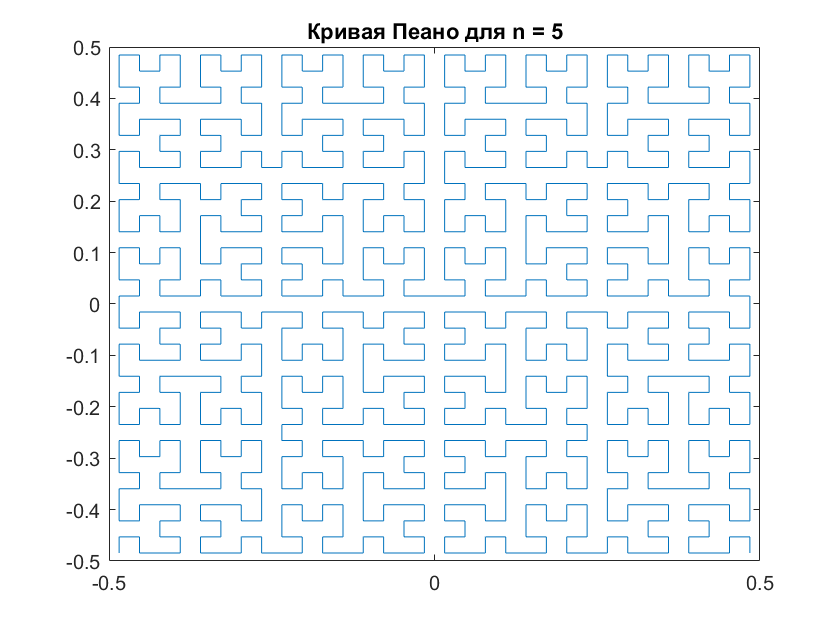

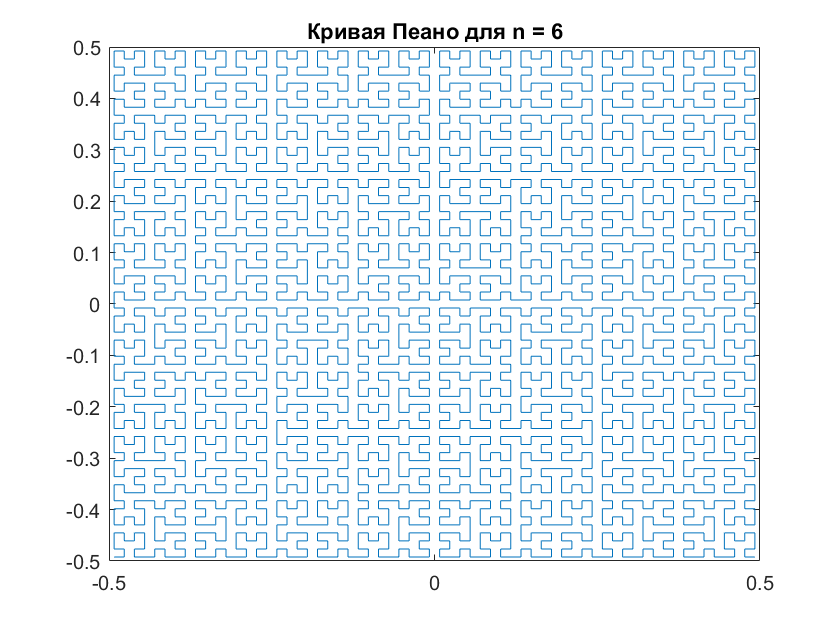

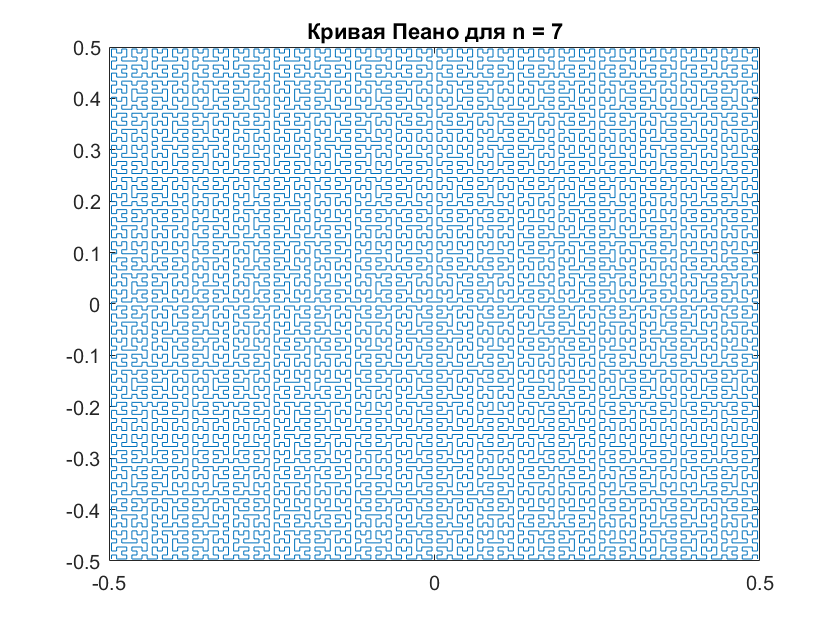


for i=1:7
    [x, y] = peano(i);
    figure(i);
    plot(x, y);
    title("Кривая Пеано для n = " + string(i))
end

function [x, y] = peano(n)
    if n <= 0
            x = 0;
            y = 0;
    else
            [x0, y0] = peano(n-1);
            x = 0.5 * [-0.5+y0 -0.5+x0 0.5+x0 0.5-y0];
            y = 0.5 * [-0.5+x0 0.5+y0 0.5+y0 -0.5-x0];
    end
end